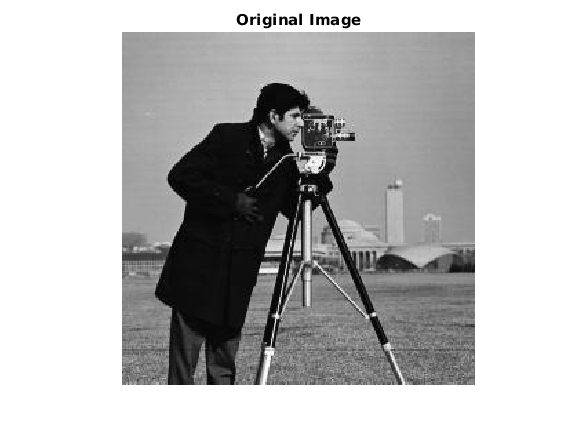

originalImage = imread('cameraman.tif');

figure
imshow(originalImage)
title('Original Image')

%Define the sizes of the three box filters.
filterSizes = [7 7;11 11;15 15];

%To pad the image to accommodate the size of the largest box filter
maxFilterSize = max(filterSizes);
padSize = (maxFilterSize - 1)/2;
paddedImage = padarray(originalImage,padSize,'replicate','both');

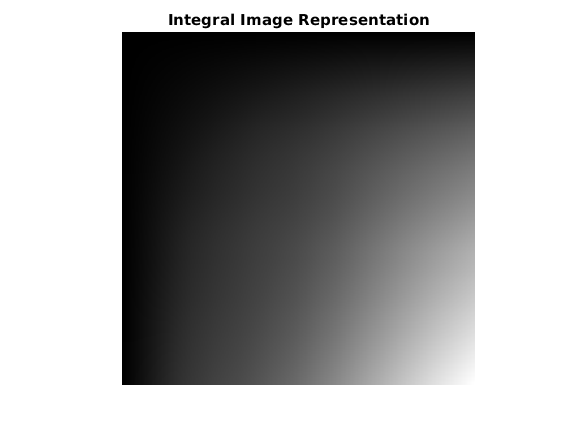

%Accessing the integral image
intImage = integralImage(paddedImage);
figure
imshow(intImage,[])
title('Integral Image Representation')

%Separaaating different sizes of filters
filteredImage1 = integralBoxFilter(intImage, filterSizes(1,:));
filteredImage2 = integralBoxFilter(intImage, filterSizes(2,:));
filteredImage3 = integralBoxFilter(intImage, filterSizes(3,:));
whos filteredImage*

  Name                  Size              Bytes  Class     Attributes

  filteredImage1      264x264            557568  double              
  filteredImage2      260x260            540800  double              
  filteredImage3      256x256            524288  double              



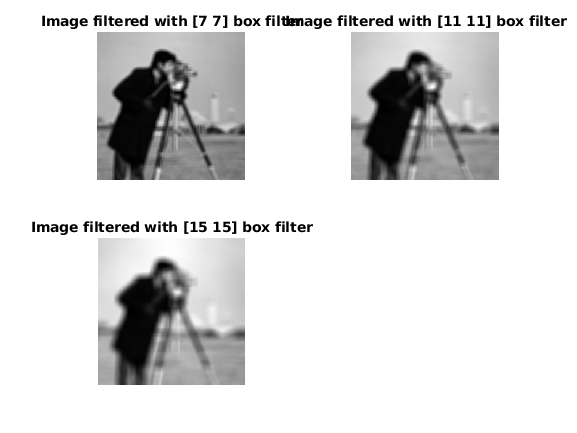

extraPadding1 = (maxFilterSize - filterSizes(1,:))/2;
filteredImage1 = filteredImage1(1+extraPadding1(1):end-extraPadding1(1),...
    1+extraPadding1(2):end-extraPadding1(2) );

extraPadding2 = (maxFilterSize - filterSizes(2,:))/2;
filteredImage2 = filteredImage2(1+extraPadding2(1):end-extraPadding2(1),...
    1+extraPadding2(2):end-extraPadding2(2) );

subplot(2,2,1),imshow(filteredImage1,[]),title('Image filtered with [7 7] box filter')
subplot(2,2,2),imshow(filteredImage2,[]),title('Image filtered with [11 11] box filter')
subplot(2,2,3),imshow(filteredImage3,[]),title('Image filtered with [15 15] box filter')